# ACO Assignment 2022 Q3 H Infinity Controller

## Load Linearized State-space plant

clc 
clear 
load linearizedModel_Outputs.mat


## Define some variables for use

s = zpk('s') %for defining transfer functions
om_rad = logspace(-2,5,1001); %define logspace range for plotting bode plot
om_rad_lin = linspace(0.5,3,1001); %define range for plotting highlight of frequency range

bw_gamma_rad = 10*0.2*2*pi %define target azimuth motion bandwith, 2pi radians is one hertz
bw_alpha_rad = 10*0.25*2*pi %define target elevation motion bandwith, 2pi radians is one hertz
    
ny = 2; %define the output dimension, for identity matrices    
THE_AXES = [-110 30];


## Design the weights individually then combine them

%Penalize high frequency input from the actuator
% W_Vgamma = 1;%same importance
% W_Valpha = 1;%same importance

W_Vgamma = 1;%5/(s + 1*bw_gamma_rad);%same importance
W_Valpha = 10/(s + 5*bw_gamma_rad)%same importance

W_Valpha =
 
     10
  ---------
  (s+62.83)
 
Continuous-time zero/pole/gain model.




Wi =mdiag(W_Vgamma,W_Valpha);
Wi = ss(Wi);

sCross_gamma = sigma(P_ss_self, bw_gamma_rad); % gives gain at a single point
sCross_alpha = sigma(P_ss_self, bw_alpha_rad); % gives gain at a single point

Wp_gamma = 1 / max(sCross_gamma(:)) % Wp_gamma = 2.7650

Wp_gamma = 2.7650

Wp_alpha = 1 / max(sCross_alpha(:)) % Wp_alpha = 4.3157

Wp_alpha = 4.3157



% Wo11 = 90*Wp_gamma/(s + 5*bw_gamma_rad)%1*bw_gamma_rad
% Wo22 = 90*Wp_alpha/(s + 5*bw_alpha_rad) %0.1*bw_alpha_rad

Wo11 = 1e2*Wp_gamma/(s + 5*bw_gamma_rad)%1*bw_gamma_rad

Wo11 =
 
    276.5
  ---------
  (s+62.83)
 
Continuous-time zero/pole/gain model.



Wo22 = 3e2*Wp_alpha/(s + 2*bw_alpha_rad) %0.1*bw_alpha_rad

Wo22 =
 
   1294.7
  ---------
  (s+31.42)
 
Continuous-time zero/pole/gain model.




% Wo11 = 35e-2/(s + 8*bw_gamma_rad);%1*bw_gamma_rad
% Wo22 = 62e-2/(s + 8*bw_alpha_rad); %0.1*bw_alpha_rad

Wo = mdiag(Wo11,Wo22)

Wo =
 
  From input 1 to output...
         276.5
   1:  ---------
       (s+62.83)
 
   2:  0
 
  From input 2 to output...
   1:  0
 
        1294.7
   2:  ---------
       (s+31.42)
 
Continuous-time zero/pole/gain model.



Wo = ss(Wo);


## Form the Weighted Plant

P_ss_self

P_ss_self =
 
  A = 
               x1          x2          x3          x4          x5          x6
   x1           0           1           0           0           0           0
   x2           0          -1  -6.847e-12           0   5.689e+04           0
   x3           0           0           0           1           0           0
   x4           0           0           0          -1           0    5.73e+04
   x5           0           0           0           0       -1000           0
   x6           0           0           0           0           0       -1000
 
  B = 
       u1  u2
   x1   0   0
   x2   0   0
   x3   0   0
   x4   0   0
   x5   1   0
   x6   0   1
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
   y2   0   0   1   0   0   0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.



Pw = Wo*P_ss_self*Wi

Pw =
 
  A = 
               x1          x2          x3          x4          x5          x6
   x1      -62.83           0          16           0           0           0
   x2           0      -31.42           0           0          32           0
   x3           0           0           0           1           0           0
   x4           0           0           0          -1  -6.847e-12           0
   x5           0           0           0           0           0           1
   x6           0           0           0           0           0          -1
   x7           0           0           0           0           0           0
   x8           0           0           0           0           0           0
   x9           0           0           0           0           0           0
 
               x7          x8          x9
   x1           0           0           0
   x2           0           0           0
   x3           0           0           0
   x4   5.689e+04           0       

## H-infinity Synthesis

## Form the controller

Cinf =  -ncfsyn(Pw);
C = Wi * Cinf * Wo;
C = minreal(C)

C =
 
  A = 
                x1          x2          x3          x4          x5          x6
   x1       -62.83  -1.153e-09   1.897e+05   -2.48e-09  -1.457e-10   9.002e+05
   x2            0      -83.98   8.471e-14          16           0           0
   x3            0   1.256e-13      -56.36           0           0          32
   x4            0      -97.01  -1.092e-13           0           1           0
   x5            0      -886.1  -1.036e-11           0          -1  -6.847e-12
   x6            0   2.334e-13      -34.21           0           0           0
   x7            0   1.845e-12      -330.8           0           0           0
   x8            0      -3.266   1.606e-09      -11.55     -0.8323   7.623e-09
   x9            0  -1.096e-14   -0.004293           0           0           0
   x10           0   1.153e-09  -1.897e+05    2.48e-09   1.457e-10  -9.002e+05
   x11           0           0           0           0           0           0
   x12           0           0         

zpk(C)

ans =
 
  From input 1 to output...
                                                                                        
       30834 (s+9.188e04) (s+1000)^2 (s+79.35) (s+62.82) (s+6.318) (s^2 + 59.37s + 2416)
                                                                                        
                                                                                        
   1:  ---------------------------------------------------------------------------------
                                                                                     
         (s+9.188e04) (s+1000)^2 (s+79.35) (s+75.34) (s+62.83) (s^2 + 56.38s + 1966) 
                                                                                     
                                                             (s^2 + 59.37s + 2416)   
                                                                                     
 
                                                                                  
    


Linf = P_ss_self*C

Linf =
 
  A = 
                x1          x2          x3          x4          x5          x6
   x1            0           1           0           0           0           0
   x2            0          -1  -6.847e-12           0   5.689e+04           0
   x3            0           0           0           1           0           0
   x4            0           0           0          -1           0    5.73e+04
   x5            0           0           0           0       -1000           0
   x6            0           0           0           0           0       -1000
   x7            0           0           0           0           0           0
   x8            0           0           0           0           0           0
   x9            0           0           0           0           0           0
   x10           0           0           0           0           0           0
   x11           0           0           0           0           0           0
   x12           0           0      

T = feedback(Linf,eye(ny));
S = eye(ny)-T;
CS = feedback(C,P_ss_self)

CS =
 
  A = 
                x1          x2          x3          x4          x5          x6
   x1       -62.83  -1.153e-09   1.897e+05   -2.48e-09  -1.457e-10   9.002e+05
   x2            0      -83.98   8.471e-14          16           0           0
   x3            0   1.256e-13      -56.36           0           0          32
   x4            0      -97.01  -1.092e-13           0           1           0
   x5            0      -886.1  -1.036e-11           0          -1  -6.847e-12
   x6            0   2.334e-13      -34.21           0           0           0
   x7            0   1.845e-12      -330.8           0           0           0
   x8            0      -3.266   1.606e-09      -11.55     -0.8323   7.623e-09
   x9            0  -1.096e-14   -0.004293           0           0           0
   x10           0   1.153e-09  -1.897e+05    2.48e-09   1.457e-10  -9.002e+05
   x11           0           0           0           0           0           0
   x12           0           0        

## Check the weighted plant with sigma

figure(3)
clf
subplot(1,2,1)
sigma(P_ss_self,Pw,om_rad)
legend ('Linear Plant', 'Weighted Plant')
grid on
subplot(1,2,2)
sigma(P_ss_self,Pw,om_rad_lin)
legend ('Linear Plant', 'Weighted Plant')
grid on


## Check the weight plant with bode

% figure(4)
% bode(P_ss_self,Pw,om_rad)
% 
% legend
% grid on


## Check robustness with multiloop input output diskmargin

[~,MM_P] = diskmargin(P_ss_self)

MM_P = struct with fields:
           GainMargin: [0.8832 1.1322]
          PhaseMargin: [-7.0982 7.0982]
           DiskMargin: 0.1240
           LowerBound: 0.1240
           UpperBound: 0.1243
            Frequency: 7.5556
    WorstPerturbation: [2×2 ss]


% DGM_P_alpha = DM_P(2).GainMargin;
% DGM_P_gamma = DM_P(1).GainMargin;

% DGMAll_P = [DGM_P_gamma;DGM_P_alpha];
DGM_P = MM_P.GainMargin;

[~,MM_Pw] = diskmargin(Pw)

MM_Pw = struct with fields:
           GainMargin: [1 1]
          PhaseMargin: [0 0]
           DiskMargin: 0
           LowerBound: 0
           UpperBound: 0
            Frequency: NaN
    WorstPerturbation: [2×2 ss]


% DGM_Pw_alpha = DM_Pw(2).GainMargin
% DGM_Pw_gamma = DM_Pw(1).GainMargin

% DGMAll_Pw = [DGM_Pw_gamma;DGM_Pw_alpha];
DGM_Pw = MM_Pw.GainMargin;

[~,MM_Linf] = diskmargin(Linf) %gets the disk margin of the robustified loop

MM_Linf = struct with fields:
           GainMargin: [0.5665 1.7653]
          PhaseMargin: [-30.9402 30.9402]
           DiskMargin: 0.5535
           LowerBound: 0.5535
           UpperBound: 0.5546
            Frequency: 18.9386
    WorstPerturbation: [2×2 ss]



DGM_Linf = MM_Linf.GainMargin;

## Plot the diskmargins

figure(6)
clf
t6 = tiledlayout(1,3,'TileSpacing','None',"Padding","none");
ax6a = nexttile

ax6a =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.0338 0.0432 0.3221 0.9387]
            Units: 'normalized'

  Show all properties


diskmarginplot(DGM_P,'disk')

ax6b = nexttile

ax6b =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.3652 0.0432 0.3174 0.9113]
            Units: 'normalized'

  Show all properties


diskmarginplot(DGM_Pw,'disk')
linkaxes([ax6a,ax6b],'x')

ax6c = nexttile

ax6c =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.6747 0.0432 0.3196 0.9113]
            Units: 'normalized'

  Show all properties


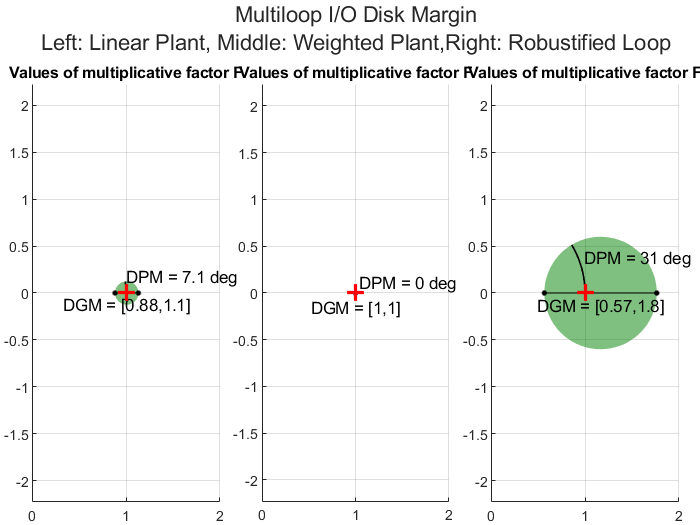

diskmarginplot(DGM_Linf,'disk')
ylim([-0.5 0.5])
linkaxes([ax6a,ax6b,ax6c],'x')
linkaxes([ax6a,ax6b,ax6c],'y')
% 
t6title = {'Multiloop I/O Disk Margin','Left: Linear Plant, Middle: Weighted Plant,Right: Robustified Loop'};
% 
% title(t6,{t6title})
title(t6,t6title)


%% 
% figure(7)
% clf
% t = tiledlayout(2,2,'TileSpacing','Compact');
% 
% nexttile
% diskmarginplot(DGM_P_gamma,'nyquist')
% nexttile
% diskmarginplot(DGM_P_alpha,'nyquist')
% nexttile
% diskmarginplot(DGM_Pw_gamma,'nyquist')
% nexttile
% diskmarginplot(DGM_Pw_alpha,'nyquist')
% title(t,{'Disk Margin for robustness within region of uncertainty','First Column: Azimuth Voltage to '})

## Plotting the sigma, S and T Responses

figure(9)
clf

subplot(121)
sigma(P_ss_self, 'm-.', Pw, 'k--', Linf, 'b-', om_rad);
% ylim(THE_AXES)
tweakAxes;
legend('P', 'Final Pw', 'Linf', 'Location', 'northeast')

sp9b = subplot(222)
ylim(THE_AXES)  
bodemag(S, 'k-', T, 'b-', CS, 'k:', om_rad);
legend
% tweakAxes;
% ylim(THE_AXES)
 ylim(sp9b, THE_AXES)
 ylim(THE_AXES)
 grid on

subplot(224)
step(T);
legend
grid

## Look at the close loop response

% figure(8)
% clf
% bode(P_ss_self,L)
% legend


## Check the robustness with rho, v-gap

figure(5)
clf
rho(P_ss_self, -eye(ny),om_rad)
hold on
rho(Pw, -eye(ny),om_rad)
grid on
rho(Pw, -Cinf,om_rad)
grid on
legend('Linear Plant','Linear Margin','Weighted Plant','Weighted Margin','Synthesised Loop','Synthesised Margin')
hold off

[~,bPC] = rho(P_ss_self, -eye(ny))
[~,bPw] = rho(Pw, -eye(ny))
[~,bPwC] = rho(Pw, -Cinf) %bPwC = 0.2690

